# PRÁCTICA 8: Segmentación de Imágenes (2ª Parte)

## CRECIMIENTO DE REGIONES

#### EJERCICIO 1

Cargue las imágenes ‘Oil Filter\oilfilt0.jpg’, ‘Gears\Parts 01.jpg’, ‘Fuse\Fuse 00.tif’ y ‘Fuse\Fuse 13.tif’ en las variables im1, im2, im3 e im4 y muéstrelas en una misma figura.

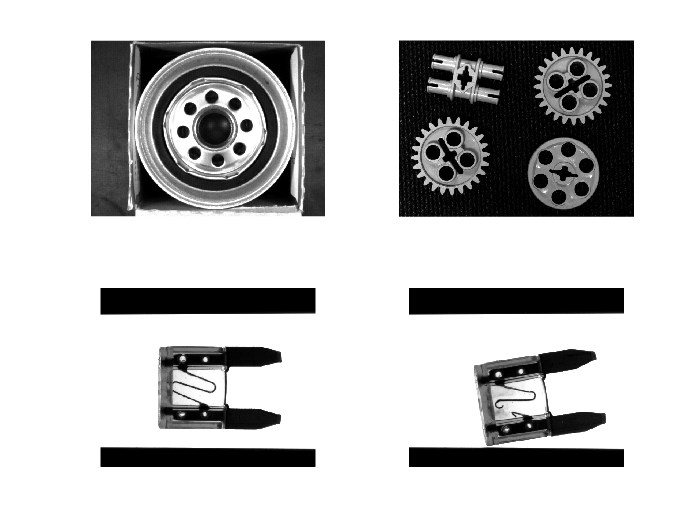

im1 = imread("OilFilt0.jpg");
im2 = imread("Parts 01.jpg");
im3 = imread("Fuse 00.tif");
im4 = imread("Fuse 13.tif");
% label2rgb en lugar de ?
figure;
subplot(2,2,1); imshow(im1);
subplot(2,2,2); imshow(im2);
subplot(2,2,3); imshow(im3);
subplot(2,2,4); imshow(im4);

#### EJERCICIO 2

Estudie el algoritmo vercre_isa y comprueba su funcionamiento para segmentar algunas regiones\objetos de las imágenes im1 e im2.

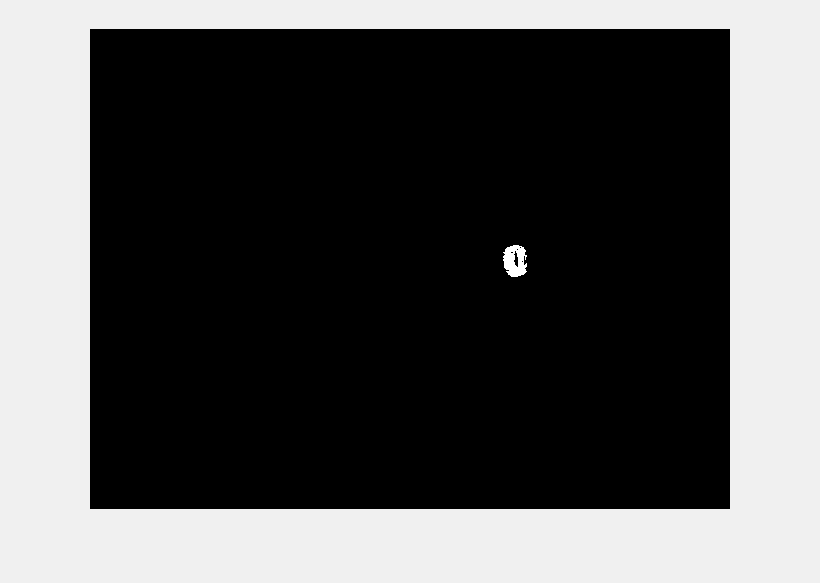

vercre_isa(im1, 10);

#### EJERCICIO 3

Utilice el algoritmo de crecimiento de regiones (umbral 80) para segmentar la mayor región central del fusible y finalmente calcule su área (bwarea). Verifique que sí el área es mayor de 5500, el fusible es defectuoso. Repita el ejercicio con otras imágenes de ‘Fuse\’.

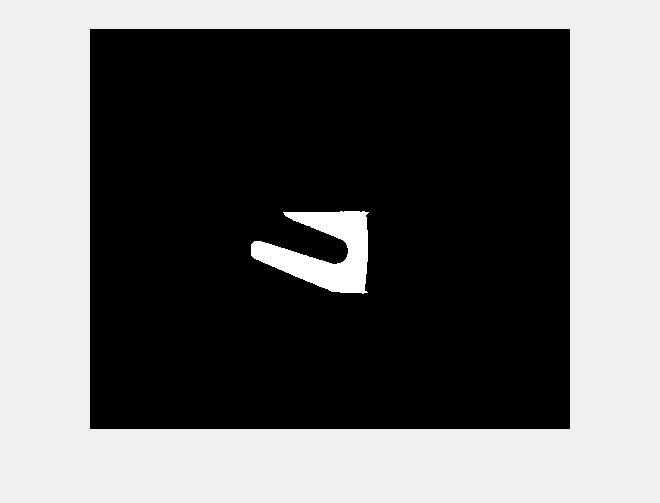

im3central = vercre_isa(im3, 80);

bwarea(im3central)

ans = 5.1161e+03

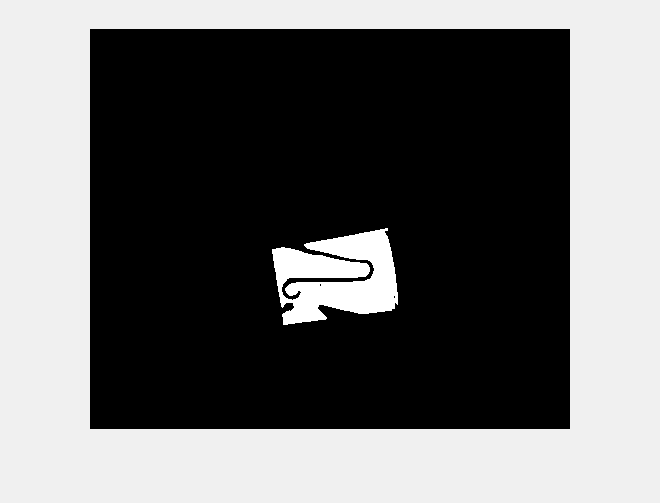

im4central=vercre_isa(im4, 80);

bwarea(im4central)

ans = 8.1284e+03

#### EJERCICIO 4

Emplee al algoritmo cre_isa para separar los objetos del fondo en la imagen im2. Para ello emplee un umbral de 50 y como posición de la semilla un pixel de fondo, por ejemplo, el (1,1). Invierta la región obtenida y muestre el resultado (im2obs).

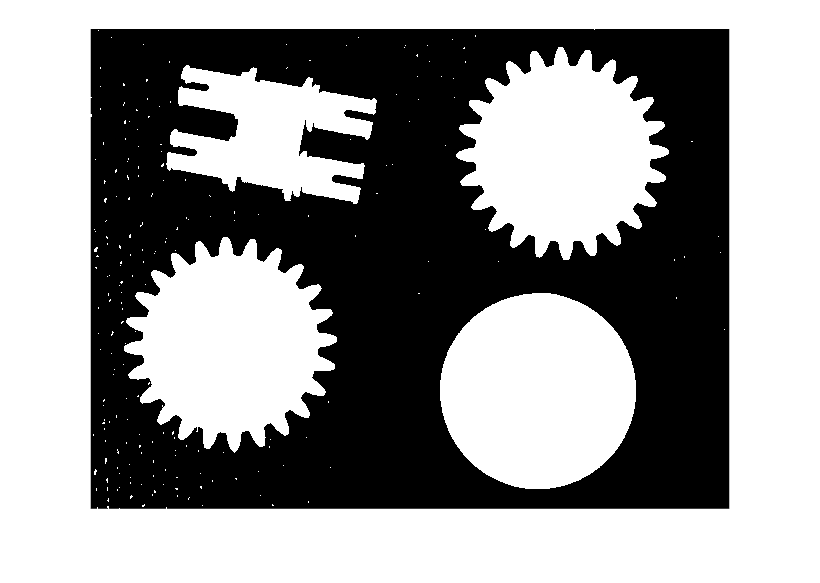

im2sep = cre_isa(im2, 50, 1, 1);
im2obs=1-im2sep;
figure;
imshow(im2obs);

## SEGMENTACIÓN DE UNA IMAGEN BINARIA MEDIANTE ETIQUETADO DE REGIONES CONECTADAS

#### EJERCICIO 5

Cargue la imagen ‘Classification\Parts00.png’ (im5) y utilice el algoritmo de etiquetado para segmentar todos los objetos contenidos en la imagen previamente binarizadas con imbinarize (im5b). La imagen etiquetada será im5L. ¿Cuántos objetos diferentes aparecen inicialmente?

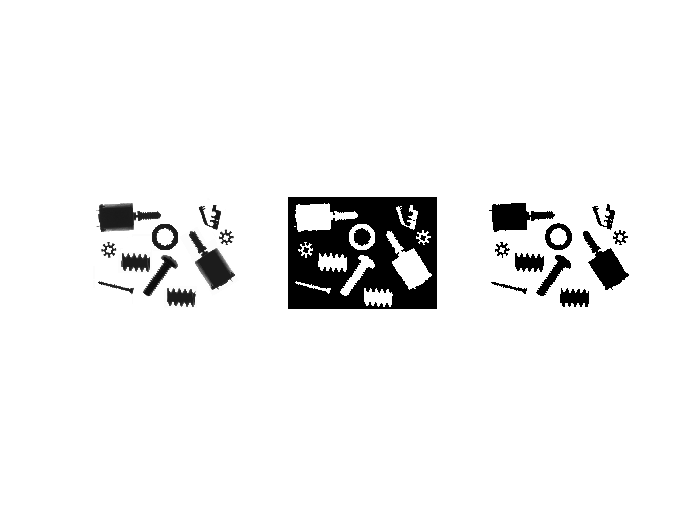

im5 = imread("Parts00.png");
im5b = not(imbinarize(im5, "global"));
im5L = bwlabel(im5b);
figure;
subplot(1,3,1); imshow(im5);
subplot(1,3,2); imshow(im5b);
subplot(1,3,3); imshow(not(im5L));

Visualice el resultado del etiquetado utilizando la paleta colorcube al mostrar la imagen.

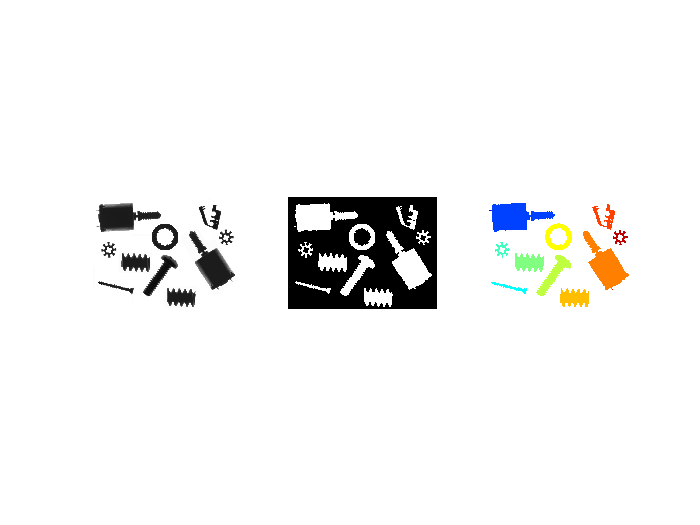

imshow(label2rgb(im5L));
% ya lo hace label 2 rgb; colormap (gca, [0 0 0; colorcube ] )

NOTA: Los objetos a etiquetar deben ser blancos y el fondo negro, de no ser así se debe invertir la imagen empleando not (imb).

#### EJERCICIO 6

Para la imagen etiquetada en el ejercicio anterior muestre una figura para cada uno de los objetos segmentados, siempre y cuando su área supere los 20 píxeles, y marcando con un ‘*’ el centroide de cada objeto.

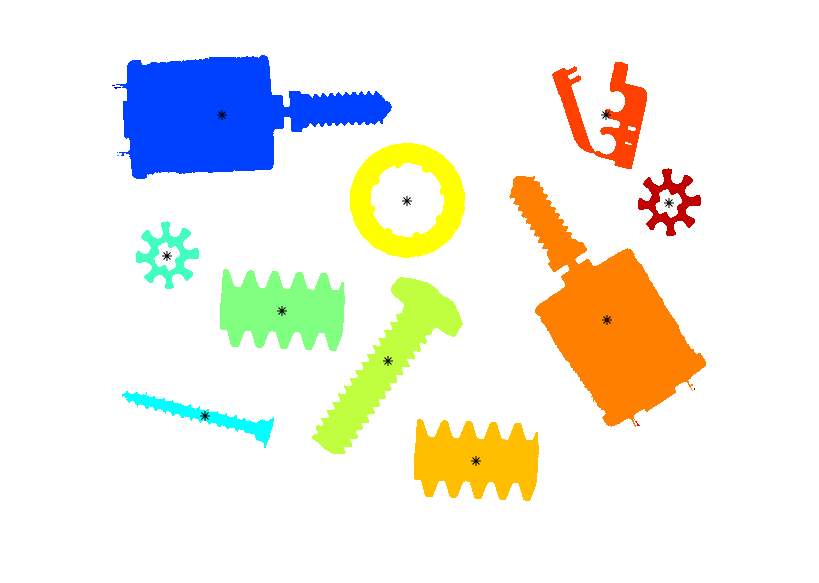

figure;
imshow(label2rgb(im5L));
hold on;
for k = 1:max(max(im5L))
    ob = (im5L == k); % seleccionar objeto con etiqueta 5k’ (número entero).
    if bwarea(ob) > 50
        [y, x] = find (ob); % ob es una imagen binaria que contiene un solo objeto
        cx = mean (x); % Coordenada X del centroide del objeto ob;
        cy = mean(y); % Coordenada Y del centroide del objeto ob;
        plot(cx, cy, 'k*');
    end
end
hold off;

#### EJERCICIO 7

Realice un script que a partir del etiquetado de regiones conectadas de la imagen im2obs, permita separar los objetos contenidos en la imagen im2 en subimágenes. Para obtener las coordenadas de la imagen que contiene un objeto binario segmentado puede emplear el código:

NOTA: se deben descartar regiones cuya área no supere un umbral determinado, evitando así errores en la umbralización debido al fondo no uniforme (ruido ambiental)

## DEFINICIÓN DE REGIONES DE INTERÉS

NOTA: Estos comandos permiten definir, mediante el uso del ratón, una región de interés sobre la imagen activa. Dicha región se podrá redimensionar y reposicionar con posterioridad, pero se elimina al cerrar la figura que contiene la imagen sobre los que se ha definido.

<máscara_binaria> = createMask (<ROI>); %Crea una máscara binaria a partir de una ROI.

<perímetro_binario> = bwperim (<máscara_binaria>, <conectividad>): %Crea una máscara de contorno.

4 u 8 (4 por defecto)

EJERCICIOS:

#### EJERCICIO 8

Cargue la imagen “Connector 01.jpg” (im6) y defina dos regiones de interés rectangulares R1 y R2 que contengan los pines de 1 al 5 y del 6 al 9.

#### EJERCICIO 9

Obtenga los parámetros de localización de las regiones mediante el comando getPosition.

>> p = getPosition (<región_de_interes>);

NOTA: p es un vector que contiene las coordenadas x e y de la esquina superior derecha y el número de pixeles en la dirección x e y.

#### EJERCICIO 10

Obtenga una subimagen de im6 empleando R1 (im6_1) la cual solo contenga los pines del 1 al 5. Binarice dicha imagen (imbinarize) y compare el resultado con la binarización de la imagen im6 completa.

>> p1 = getPosition (R1); % Posición y tamaño de R1

>> im6_1 = imcrop (im6,p1); % Subimagen de R1

>> imshow (im6_1);

#### EJERCICIO 11

Cree tres máscaras binarias MB1, MB2 y MB3 para los pixeles de la región R1, los de la región R2 y los de las regiones R1 y R2. Visualice los pixeles de la imagen im7 seleccionados mediante la máscara MB3 (im6_2) :

>> im6_2 = double (im6) .* MB3; % Pone a cero lo que no esté en la máscara

>> imshow (im6_2, [ ] );

## PROGRAMA INSPECCIÓN DE DISPENSADORES (ADICIONAL)

a) Cargue la secuencia de imágenes contenidas en la carpeta \Spray\ por medio del SCRIPT ‘CargarSpray’. Cada una de las imágenes contiene un dispensador de jabón cuya posición en el eje X puede variar. El script anterior muestra en una figura las 12 imágenes cargadas (sp1, sp2, … sp12) y una región de interés tipo línea empleada para la inspección de los dispensadores.

b) El siguiente código realiza la inspección de una imagen Spray e indica si el correcto o no. Pruebe dicho programa con diversas imágenes (programa ‘AnalizarSpray.m’)

c) Modifique el programa anterior para que indique cuando el dispensador es defectuoso y cuando el tapón está ausente:

 DISPENSADOR CORRECTO ó DISPENSADOR INCORRECTO (en la línea 20);

 TAPÓN PRESENTE ó TAPÓN AUSENTE (en la línea 50)

NOTA: un dispensador es correcto siempre que contenga el pulsador, tenga o no tapón,